clc
clear

cd '/users/mkb21147/Documents/Final_PhD_Simulations/Structure_Models/Abaqus_Metal_Phase_transf/Structure_Model_using_Abaqus/data'



## Set input file


temperature_file = 'Cube_Temperature_Element_at_heigt_0.06.csv'

temperature_file = 'Cube_Temperature_Element_at_heigt_0.06.csv'

## Pre-process job with python

command = append('. ../src/conda_initialise-3.9.sh && conda activate Process_Simulation_2 && python ../src/main.py ',temperature_file);
system(command)

ans = 0

## Run Abaqus Job

status = system('module load abaqus/2020 && abaqus job=structure_model ask_delete=OFF interactive')

Analysis initiated from SIMULIA established products
Abaqus JOB structure_model
Abaqus 2020.HF6
Abaqus License Manager checked out the following licenses:
Abaqus/Standard checked out 5 tokens from Flexnet server abaqus.license.strath.ac.uk.
<444 out of 516 licenses remain available>.
Begin Analysis Input File Processor
Fri 24 Nov 2023 11:27:18 AM GMT
Run pre
Fri 24 Nov 2023 11:27:19 AM GMT
End Analysis Input File Processor
Begin Abaqus/Standard Analysis
Fri 24 Nov 2023 11:27:19 AM GMT
Run standard
Fri 24 Nov 2023 11:28:42 AM GMT
End Abaqus/Standard Analysis
Begin SIM Wrap-up
Fri 24 Nov 2023 11:28:42 AM GMT
Run SMASimUtility
Fri 24 Nov 2023 11:28:42 AM GMT
End SIM Wrap-up
Abaqus JOB structure_model COMPLETED


status = 0

## Read history outputs from odb

status = system('module load abaqus/2020 && abaqus cae noGUI=../src/Abaqus_PBF_Structure_model/read_history_outputs.py')

Abaqus License Manager checked out the following license:
"cae" from Flexnet server abaqus.license.strath.ac.uk
<18 out of 22 licenses remain available>.


status = 0

## Plot data

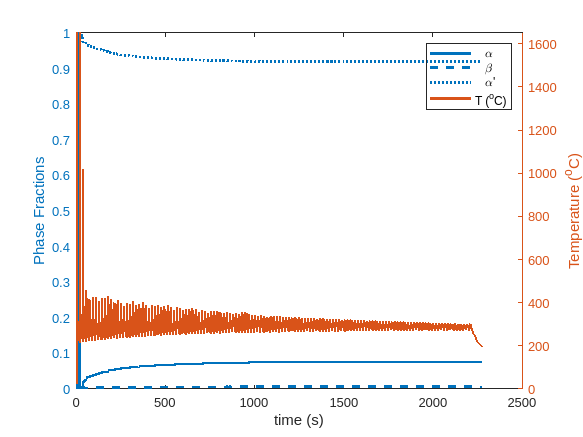

close all

alpha = readmatrix('alpha.csv');
beta = readmatrix('Beta.csv');
mart = readmatrix('mart.csv');
TEMP = readmatrix('TEMP.csv');

time = TEMP(:,1);

yyaxis left
plot(time, alpha(:,2),'LineWidth',2)
hold on
plot(time, beta(:,2),'LineWidth',2)
plot(time, mart(:,2),'LineWidth',2)
ylabel('Phase Fractions')

yyaxis right
plot(time, TEMP(:,2),'LineWidth',2)
ylabel('Temperature (^{o}C)')

ylim([0 1650])

lgnd = legend('   \alpha','   \beta',"   \alpha'",'T (^{o}C)');
set(lgnd,'color','none');
xlabel('time (s)')

hold off

## Calculate lath thickness


$$\textrm{�}$$



$$\textrm{�}$$


temp = TEMP(:,2);
falpha = alpha(:,2);

k = 1.42;
R=294;
t0 = 1

t0 = 1

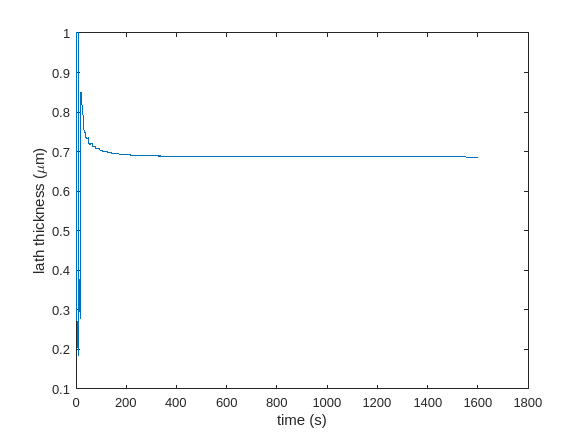


tlath = zeros([length(time) 1]);

tlath(1) = t0;
for i=2:1:length(time)

    teq = k * exp(-R/temp(i));
    
    if falpha(i) > 0
        tlath(i) = (tlath(i-1) - teq) * falpha(i-1)/falpha(i) + teq;
    else
        tlath(i) = t0;
    end

 
end
figure()
plot(time,tlath)
xlabel('time (s)')
ylabel('lath thickness ({\mu}m)')


writematrix(tlath,'tlath.csv') 


$$\textrm{�}$$


- Q is activation energy, 97 Kj/mol

- ko is the kinetic constant = 20um^3/s for alpha and 2*10^7 um/s^3 for beta

- Do is initial grain size, 1 for alpha

- Di is the current grain size

- T is the heat treatment temperature